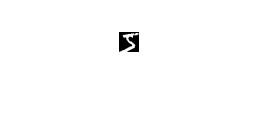

[ims, labels] = readMNIST('train-images-idx3-ubyte', 'train-labels-idx1-ubyte', 20, 0);
imshow(ims(:,:,1))

labels(1)

ans = 5

Agafar el 80% com a mostra i 20% per testejar el model

% [rows, cols, nims] = size(ims)
% sample = ims(:,:, 1:floor(nims*0.8));
% test = ims(:,:, floor(nims*0.8)+1:end);

data = regionprops(ims(:,:,1), 'all');
data2 = regionprops(ims(:,:,2), 'all');

[ims, labels] = readMNIST('train-images-idx3-ubyte', 'train-labels-idx1-ubyte', 2000, 0);
areas = [];
convexArea = [];
hough = [];

for i=1:size(ims, 3)
    im = ims(:,:,i);
    imb = imbinarize(im);
    %Area
    areas = [areas; bwarea(imb)];
    convexArea = [convexArea; bwarea(imbinarize(imsubtract(bwconvhull(imb), imb)))];
    %Transformada de Hough
    longLines = houghTransform(im);
    houghValues = [longLines.point1, longLines.point2, longLines.theta, longLines.rho];
    hough = [hough; houghValues];   
end

Unable to perform assignment because dot indexing is not supported for variables of this type.

t = table(areas, convexArea, hough(1:size(areas, 1),:), labels(1:size(areas, 1)));